# Mass damper spring system

In this example we will consider the following system.

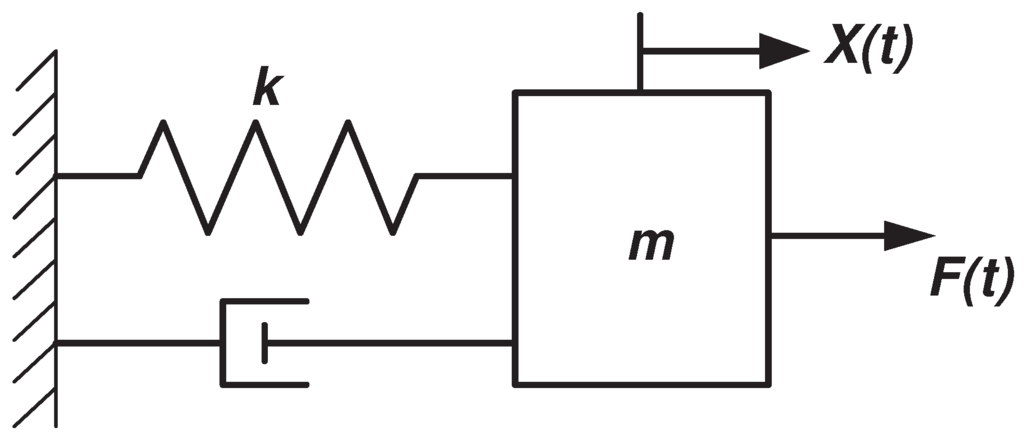

This system has the following state space representation:


$$\pmatrix{\dot{x} \cr \ddot{x}} = 
\pmatrix{0 & 1 \cr \frac{-k}{M} & \frac{-f_v}{M}}
\pmatrix{x \cr \dot{x}} +
\pmatrix{0 \cr \frac{1}{M}} u$$


k = 1;
M = 1;
f = 1;
A = [0 1 ; -k/M -f/M];
B = [0 ; 1/M];
C = [1 0 ; 0 1];
D = [];
sys_mds_c = ss(A,B,C,D);

## Impulse response

For this example we will consider data generated by the impulse response of this system.

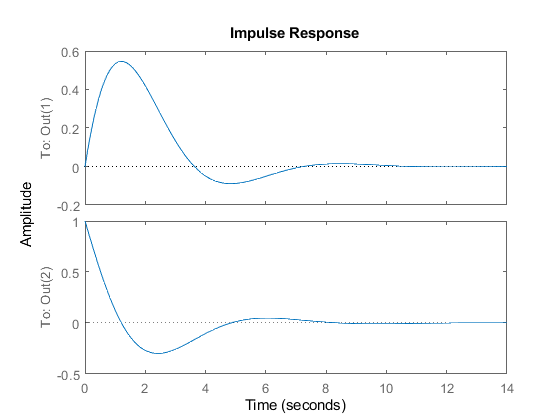

impulse(sys_mds_c)

[y_impulse, t_impulse, x_impulse] = impulse(sys_mds_c);

### Defining the data

We will first consider all `150` datapoints generated by the impulse function. Since we are considering the impulse responce we have that our input is infinitly small and thus bassically non existing. Because of this we can only use the impulse respons to find the $A$ matrix of the system, since we are considering the system as if it had no input. But first we need to put the data as returned by the impulse function in the correct format.

X_impulse = x_impulse.';

### System identification

We can check if the data is informative for system identification by using `[bool, A, B] = isIdentifiable(X, U)`. For this to be the case we need that the data is full rank, i.e.:


$$rank \pmatrix{X_- \cr U_-} = n + m$$


Since we use the impulse function we know that $U_-
$ is empty and $m$ is zero. Hence we only need to find 2 linearly independant columns in our data points. From this we can see that the use of 150 data points is a bit eccesive, hence we also consider some cases below where we reduce the amount of data points.

disp("Is the data informative for system identification?");

Is the data informative for system identification?


[bool, A_impulse] = isInformIdentification(X_impulse)

bool = logical
   1


A_impulse =     0.9959    0.0879
   -0.0879    0.9080


We will verify the received $A_{impulse}$ matrix by comparing it to the actual $A$ matrix

#### Verifying results

We can check the validity of the results by comparing them against the continuous time version of the system. To get the continuous time system we use the [`sysc = d2c(sysd)`](https://nl.mathworks.com/help/control/ref/d2c.html#d122e34030) function provided by Matlab. We can find the timestep of the data by inspecting the `t_impulse` array that was returned by the impuls function

disp("What does the obtained system look like in continuous time form?")

What does the obtained system look like in continuous time form?


sys_impulse_d = ss(A_impulse, [], C, D, t_impulse(2));
sys_impulse_c = d2c(sys_impulse_d)

sys_impulse_c =
 
  A = 
              x1         x2
   x1  -3.24e-15          1
   x2         -1         -1
 
  B = 
     Empty matrix: 2-by-0
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
     Empty matrix: 2-by-0
 
Continuous-time state-space model.



Recall that the true system is given by:


$$\dot{\mathbf{x}} = 
\pmatrix{0 & 1 \cr -1 & -1}
\mathbf{x} +
\pmatrix{0 \cr 1} 
\mathbf{u}$$


As we can see we can retreive all the information about the $A
$ matrix using the imulse response of the system. But to retreive the $B$ matrix we need a non zero input for the system. For this we will consider the step response. But first we will look if the data is informative for stability.

### Stability

There are a lot of methods to see if a system is stable. The easiest one whould be to plot the data and see if it converges. By looking at the plot of the impulse response we can see that the system is most likely stable. Another option would be to consider the eigenvalues of the $A$ matrix of the system and see if they are stable. However, lets assume that we want a more automated way of verifing that the data is stable without neccesarilly knowing the true system. In that case we can use the function `bool = isInformStable(X)`.

disp("Is the data informative for stability?");

Is the data informative for stability?


disp(isInformStable(X_impulse));

   1



## Step response

As noted above, we will use the step response to retrieve the $A$ and $B$ matrix describing the system.

### Defining data

We will start by considering all 150 data points generated by the step function. We will see later on that this is excessive and that we can use less points for the same result. Since the step function is a constant unit input, we will define $U_-$ in the following way:

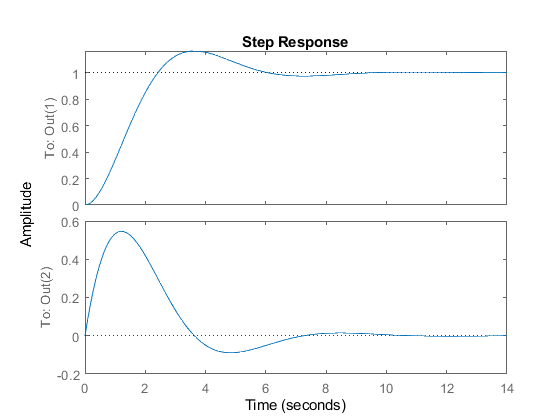

step(sys_mds_c)

[y_step, t_step, x_step] = step(sys_mds_c);
U_step = ones(1,149);
X_step = x_step.';

### System identification

To see if the data is informative for system identification we will once again consider the following function:

`[bool, A, B] = isIdentifiable(X, U)`

disp("Is the data informative for system identification?");

Is the data informative for system identification?


[bool, A_step, B_step] = isInformIdentification(X_step, U_step)

bool = logical
   1


A_step =     0.9959    0.0879
   -0.0879    0.9080


B_step =     0.0041
    0.0879


As we can see the data is still informative for system identification.

#### Verifying results

We will once again check the validity of the data by first converting the system back to a continuous time system using the [`sysc = d2c(sysd)`](https://nl.mathworks.com/help/control/ref/d2c.html#d122e34030) function provided by Matlab, using the same timestep as the data, namely `t_step(2)`.

disp("What does the obtained system look like in continuous time form?")

What does the obtained system look like in continuous time form?


sys_step_d = ss(A_step, B_step, C, D, t_step(2));
sys_step_c = d2c(sys_step_d)

sys_step_c =
 
  A = 
              x1         x2
   x1  4.822e-15          1
   x2         -1         -1
 
  B = 
              u1
   x1  3.466e-15
   x2          1
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



As we can see we get the valid $A$ and $B$ matrix (up to working precision). Thus we can conclude that the impulse response is insufficient for finding the $B$ matrix of this system. It is however still informative for identification of the $A$ matrix. The step response however is sufficient for finding both the $A$ and $B$ matrix of this system. 

`Even though we have found the system to be uniquely identifiable, we will still see if we can infer other properties from the data. We will then confirm these properties based on our knowledge of the true system.`

## Non constant input

We are trying to identify a descrete time system based on measurement data of a continuous time system. Up until this point we where able to infere the system from the data since we were considering a constant input. `However, do these methods still work if we consider a non constant input?`

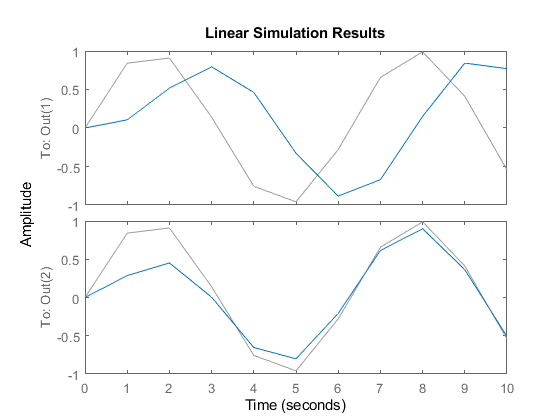

t = 0:1:10;
u = sin(t);
lsim(sys_mds_c, u, t)

[y_nc, t_nc, x_nc] = lsim(sys_mds_c, u, t);
X_nc = x_nc';
U_nc = u(:,1:end -1);

We will now check if the data is still informative for system identification.

[bool, A_nc, B_nc] = isInformIdentification(X_nc, U_nc)

bool = logical
   1


A_nc =     0.5292    0.4281
   -0.8854   -0.1581


B_nc =     0.3819
    0.6458


As we can see the data is still informative for system identification. 

disp("What does the obtained system look like in continuous time form?")

What does the obtained system look like in continuous time form?


sys_nc_d = ss(A_nc, B_nc, C, D, t(2));
sys_nc_c = d2c(sys_nc_d)

sys_nc_c =
 
  A = 
           x1      x2
   x1  0.2126   1.024
   x2  -2.119  -1.432
 
  B = 
            u1
   x1  -0.1275
   x2    1.595
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



Even though the data is informative for identification, the resulting system is not very close to the actual system. This is because a discrete time system assumes the input to be constant inbetween time steps instead of being continuously changing. We will now see what the impact of sample rate is on the data. We will consider the same amount of data points for each case. We will also keep track of the total element wise error of A and of B and plot this.

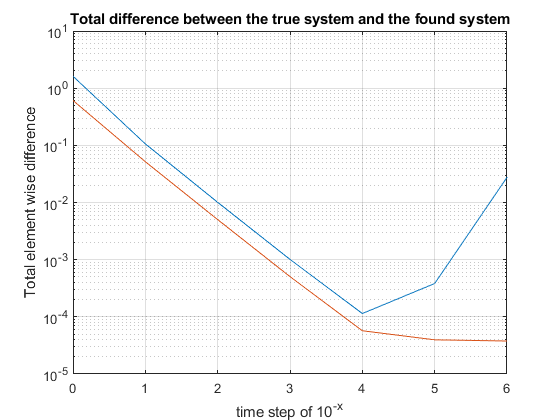

t = 0:1e5;
range = 0:6;
a_dif = zeros(size(range));
b_dif = zeros(size(range));
for idx = range
    t_temp = t * 10^-idx;
    u_temp = sin(t_temp);
    [x_temp] = lsim(sys_mds_c, u_temp, t_temp);
    [bool, A_temp, B_temp] = isInformIdentification(x_temp', u_temp(:,1:end -1));
    if bool
        sys_temp = d2c(ss(A_temp, B_temp, C, D, t_temp(2)));
        a_dif(idx + 1) = sum(sum(abs(A - sys_temp.A)));
        b_dif(idx + 1) = sum(sum(abs(B - sys_temp.B)));
    end
end

semilogy(range, a_dif, range, b_dif)
title('Total difference between the true system and the found system')
xlabel('time step of 10^{-x}')
ylabel('Total element wise difference')
grid on;

As we can see the accuracy will increase if we decrease the measurement interval. However, as we can see the error will increase for x greater than 4. This is because the data points are to close together and do not describe enough of the response. Thus it is possible to identify the true system using non constant input if the measurement interval aproaches zero and the measurements are taken for 'long enough'. However, in practice it might be a lot easier to use a constant input to identify the system because then you do not have to consider the effects of zero order hold.

## Controllability

In this section we will see if the data is informative for controllability. For this we will consider the data obtained from the step function since it is informative for accurate system identification. We can check this using the function `bool = isControllable(X)`.

disp("The step function data is informative for controllability?");

The step function data is informative for controllability?


disp(isInformControllable(X_step));

   1



As we can see the data is informative for controllability. We can verify this by means of the reachability matrix of the actual system.

disp("The system is controllable?");

The system is controllable?


disp(rank([B A*B]) == 2);

   1



## Stabilisability

In this section we will see if the data is informative for stabilisability. We can check if the data is informative for stabilisability by using the function `bool = isStabilisable(X)`.

disp("The data is informative for system stabilisability?");

The data is informative for system stabilisability?


disp(isInformStabilisable(X_step))

   1



As expected, the data is informative for stabilisability. This is what we would expect since if a system is controllable it should also be stabilisable.

## State feedback

Since our system is controllable, we might want to find a state feedback controller, in this example it is unneccesary since the system is already stable, but lets assume we are not aware of this. To find a full state feedback controller for the descrete system, we can use the function `[bool, K] = StateFeedbackYalmip(X, U)`.

[bool, K] = StateFeedbackYalmip(X_step, U_step);

Since the data is informative for system identification, we can verify if the resulting closed loop system will be stable.

disp("Is the data informative for state feedback?");

Is the data informative for state feedback?


disp(bool);

   1



disp("The eigenvalues of A+BK are:");

The eigenvalues of A+BK are:


disp(eig(A_step + B_step * K));

   0.9996 + 0.0182i
   0.9996 - 0.0182i



disp("Their magnitude is:");

Their magnitude is:


disp(abs(eig(A_step + B_step * K)));

    0.9998
    0.9998



Thus the provided controller is indeed a stabilizing controller for the descrete time system, al be it a slow one. Currently it is not possible to place the poles for the given controller, this is because the controller should work for all systems that are described by the data. Hence we are not always able to place our poles in arbitrary positions. You can find an example of this in the `Example/ex_no_identification.mlx` file.

However, this controller is only valid for the descrete time case. `We will now check if we can convert it to a valid continuous time controller.`

sys_step_cl_d = ss(A_step + B_step * K, [], [1 0;0 1], [], t_step(2));
sys_step_cl_c = d2c(sys_step_cl_d);


## Deadbeat control

Since our system is controllable, we might want to find a deadbeat controller. A deadbeat controller is a controller that brings the system to a stable state in `1` iterarion. This is done by finding a controller that assigns the eigenvalues of the closed loop system to zero. To do this we will use the function `[bool, K] = isInformDeadbeatControl(X, U)`.

[bool, K] = isInformDeadbeatControl(X_step(:,1:5), U_step(:,1:4))

bool = logical
   1


K =  -122.4816  -15.9375


disp("Is the data informative for deadbeat control?");

Is the data informative for deadbeat control?


disp(bool);

   1



disp("What is the corresponding controller?");

What is the corresponding controller?


disp(K);

 -122.4816  -15.9375



disp("The eigenvalues of the closed loop system are:")

The eigenvalues of the closed loop system are:


disp(eig(A_step + B_step * K))

   1.0e-06 *

    0.1803
   -0.1803



## How much data is needed and what is the precision

We will now look at how much data we need for system identification, for this we will check the first `n` entries of the step response data. We will also use these results to check the consistency of the result based on the amount of data provided.

n = 149;
isIdentifiable = [];
a11 = []; a12 = []; a21 = []; a22 = [];
b1  = []; b2  = [];
for idx = 1:n
    [bool,A_tmp,B_tmp] = isInformIdentification(X_step(:,1:idx+1), U_step(:,1:idx));
    if bool
        isIdentifiable = [isIdentifiable idx];
        a11 = [a11 A_tmp(1,1)];
        a12 = [a12 A_tmp(1,2)];
        a21 = [a21 A_tmp(2,1)];
        a22 = [a22 A_tmp(2,2)];
        b1  = [b1  B_tmp(1)];
        b2  = [b2  B_tmp(2)];
    end
end

From this we can inspect the `isIdentifiable` array and see for how many data points the data is informative for system identification. As we noted earlier, we only needed `3` linearly independant collumns (since $U_-$ is not empty for the step function), which where the 1st, 2nd and 3rd collumn in this case.

disp("How many data points are needed for system identification?:")

How many data points are needed for system identification?:


isIdentifiable

isIdentifiable =      3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52


We can also verify that the received $A
$ matrix is consistent. To do this we will normilize out `a11, a12, ..., b2` with the actual $A$ and $B$ matrix and plot the error.

`TODO: plot legend not working correct, fix later.`

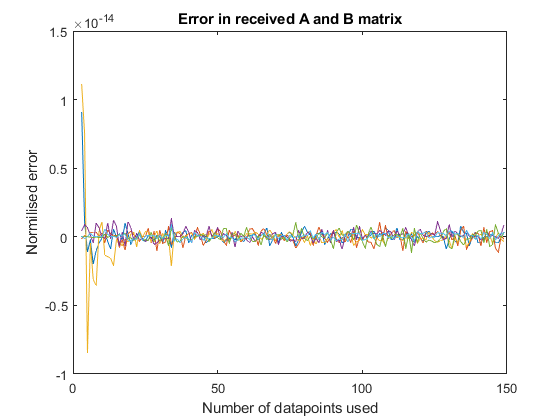

% Converting the continuous true system to a discrete system.
sys_mds_d = c2d(sys_mds_c, t_impulse(2));

x = isIdentifiable;
plot(x, a11 - sys_mds_d.A(1,1), 'DisplayName', 'a11');
hold on
plot(x, a12 - sys_mds_d.A(1,2), 'DisplayName', 'a12');
plot(x, a21 - sys_mds_d.A(2,1), 'DisplayName', 'a21');
plot(x, a22 - sys_mds_d.A(2,2), 'DisplayName', 'a22');
plot(x, b1  - sys_mds_d.B(1),   'DisplayName', 'b1');
plot(x, b2  - sys_mds_d.B(2),   'DisplayName', 'b2');
title("Error in received A and B matrix");
xlabel("Number of datapoints used");
ylabel("Normilised error");
%legend;
hold off

As we can see the received $A$ and $B$ matrix are consistent up to machine precision.

## What is the impact of sampling moment?

We will now consider what happence when we skip the first few entries. We want that the result stays consistent independant of when we sample the system. Thus we use the following code to generate $A
$ and $B$ using increasingly more data. 

n = 100;
isIdentifiable = [];
a11 = []; a12 = []; a21 = []; a22 = [];
b1  = []; b2  = [];
for idx = 1:n
    [bool,A_tmp,B_tmp] = isInformIdentification(X_step(:,idx:end), U_step(:,idx:end));
    if bool
        isIdentifiable = [isIdentifiable idx];
        a11 = [a11 A_tmp(1,1)];
        a12 = [a12 A_tmp(1,2)];
        a21 = [a21 A_tmp(2,1)];
        a22 = [a22 A_tmp(2,2)];
        b1  = [b1  B_tmp(1)];
        b2  = [b2  B_tmp(2)];
    end
end

We can now normalize and plot the data to see what happens with the error.

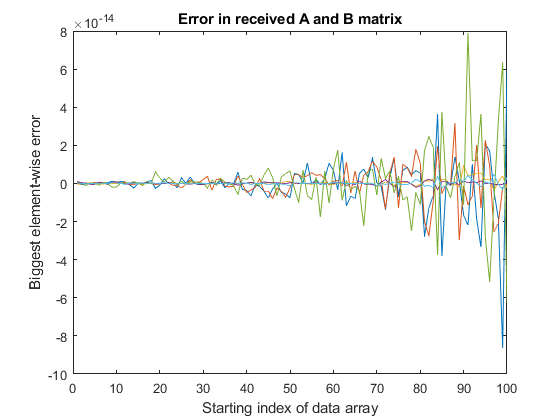

x = isIdentifiable;
plot(x, a11 - sys_mds_d.A(1,1), 'DisplayName', 'a11');
hold on
plot(x, a12 - sys_mds_d.A(1,2), 'DisplayName', 'a12');
plot(x, a21 - sys_mds_d.A(2,1), 'DisplayName', 'a21');
plot(x, a22 - sys_mds_d.A(2,2), 'DisplayName', 'a22');
plot(x, b1  - sys_mds_d.B(1),   'DisplayName', 'b1');
plot(x, b2  - sys_mds_d.B(2),   'DisplayName', 'b2');
title("Error in received A and B matrix");
xlabel('Starting index of data array');
ylabel('Biggest element-wise error');
%legend;
hold off

As we can see the error is relativly small but increasing. This is due to noice introduced by floating point inaccuracies when the system is almost in a stable state.